# **Assignment:  Feature Classification  of CWRU Dataset**

**Name: 김인엽  **

## **Introduction**

**Due in 1 week.**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of classification in the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Apply KNN and SVM  classification methods with all  features **

**3. Apply KNN and SVM  classification methods with Selected features by Forward/Backward eliminiation**

- Read here: [https://kr.mathworks.com/help/stats/sequentialfs.html](https://kr.mathworks.com/help/stats/sequentialfs.html)

**4. Apply KNN and SVM  classification with Reduce feature dimension by PCA or LDA**

- Read here:  https://kr.mathworks.com/help/stats/pca.html?lang=en

You have to show necessary steps and plots/data with proper comments

Which gives the best evaluation performance on Test set? Also try to optimize KNN and SVM

## Dataset

**Given: Feature Extracted from CWRU bearing dataset **

You are provided with train and test dataset consists of CWRU data features. 

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Feature_data.zip**  

- `/Dataset/CWRU_selected_dataset/Feature_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Feature_data/`

You can refer to the previous Assignment: FeatureExtraction CWRU `IAIA_Assignment_CWRU_FeatureExtraction_student.mlx`

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

The given data is divided by Train set and Test set 

**Note**

Training. K-fold, cross-validation is performed on Train Dataset only.

Test dataset is used for Evaluation.

## Load Dataset

close all
clear



% Train set
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");


% Test set
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");



## **Section 1: Classification with all features**

You need to explain the process cleary and analyze the results

**Classfier 1: SVM**

For multi-class SVM, use      **fitcecoc( )**

[https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en](https://kr.mathworks.com/help/stats/fitcecoc.html?lang=en)

Xtrain = glob_all_train{:,:};
Ytrain = categorical(class_cwru_train);

Xtest = glob_all_test{:,:};
Ytest  = categorical(class_cwru_test);

t = templateSVM("KernelFunction","rbf","BoxConstraint",1);

mdl = fitcecoc(Xtrain, Ytrain, "Learners", t, "ClassNames", unique(Ytrain));

trainLoss = resubLoss(mdl);
trainLoss

trainLoss = 0

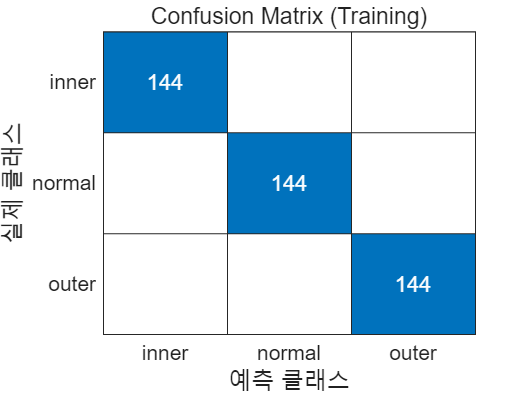

% SVM train confusion matrix
predTrain = predict(mdl, Xtrain);
predTrain = categorical(predTrain);
figure;
confusionchart(Ytrain, predTrain);
title("Confusion Matrix (Training)");

trainAccuracy = mean(predTrain == Ytrain);
fprintf("Training Accuracy = %.4f (%.2f%%)\n", trainAccuracy, trainAccuracy*100);

Training Accuracy = 1.0000 (100.00%)


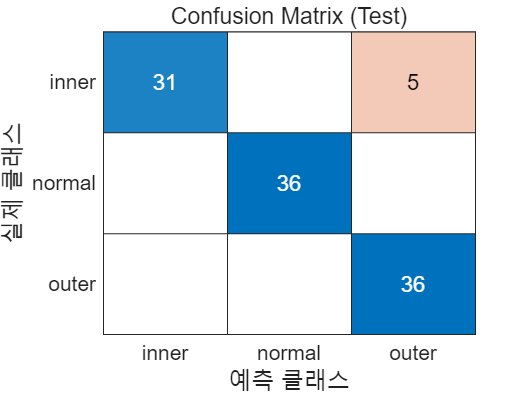

% SVM test confusion matrix
predTest = predict(mdl, Xtest);
predTest = categorical(predTest);

figure;
confusionchart(Ytest, predTest);
title("Confusion Matrix (Test)");

testAcc = mean(predTest == Ytest)

testAcc = 0.9537

%% 10-Fold Cross Validation
rng(0);

cvmdl = crossval(mdl, "KFold", 10);

cvLoss = kfoldLoss(cvmdl);      % Average Loss
cvAccuracy = 1 - cvLoss;        % Accuracy

fprintf("10-Fold CV Loss  : %.4f\n", cvLoss);

10-Fold CV Loss  : 0.0486


fprintf("10-Fold CV Acc   : %.4f (%.2f%%)\n", cvAccuracy, cvAccuracy*100);

10-Fold CV Acc   : 0.9514 (95.14%)


**Classifier 2: KNN**

feature1 = "sv";     % skewness value
feature2 = "ipf";    % impulse factor

% Train
Xtrain_knn(:,1) = table2array(glob_all_train(:, feature1));
Xtrain_knn(:,2) = table2array(glob_all_train(:, feature2));
Ytrain_knn      = categorical(class_cwru_train);

tbl_knn = table(Xtrain_knn(:,1), Xtrain_knn(:,2), Ytrain_knn);

% Test
Xtest_knn(:,1) = table2array(glob_all_test(:, feature1));
Xtest_knn(:,2) = table2array(glob_all_test(:, feature2));
Ytest_knn      = categorical(class_cwru_test);

tblTest_knn = table(Xtest_knn(:,1), Xtest_knn(:,2), Ytest_knn);

%% Train KNN Classifier
rng(10);
K = 3;
mdl_knn = fitcknn(tbl_knn, 'Ytrain_knn', ...
    'NumNeighbors', K, 'Standardize', true);

%% Training Loss
trainLoss_knn = resubLoss(mdl_knn);
fprintf("KNN Train Loss = %.4f\n", trainLoss_knn);

KNN Train Loss = 0.0116


%% Cross-validation
cvMdl_knn = crossval(mdl_knn, 'KFold', 10);
cvLoss_knn = kfoldLoss(cvMdl_knn);
fprintf("KNN 10-fold CV Loss = %.4f\n", cvLoss_knn);

KNN 10-fold CV Loss = 0.0116


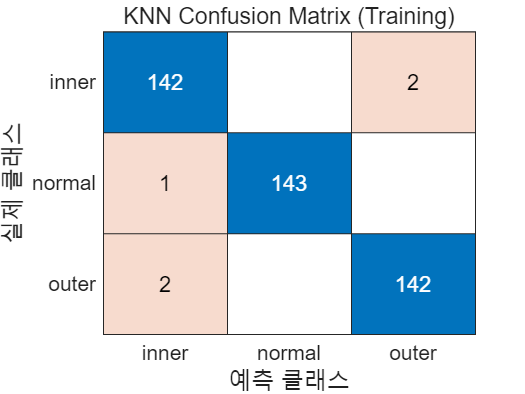

%% KNN train confusion matrix
predTrain_knn = predict(mdl_knn, tbl_knn);
predTrain_knn = categorical(predTrain_knn);

figure;
confusionchart(Ytrain_knn, predTrain_knn);
title("KNN Confusion Matrix (Training)");

%% Test Prediction & Test Loss
predTest_knn = predict(mdl_knn, Xtest_knn);
predTest_knn = categorical(predTest_knn);

testLoss_knn = mean(predTest_knn ~= Ytest_knn);

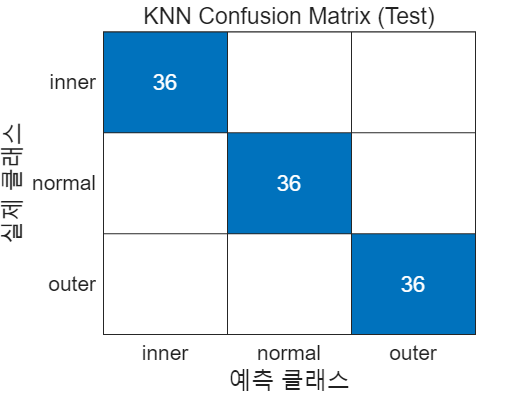

%% KNN Test confusion matrix
figure;
confusionchart(Ytest_knn, predTest_knn);
title("KNN Confusion Matrix (Test)");

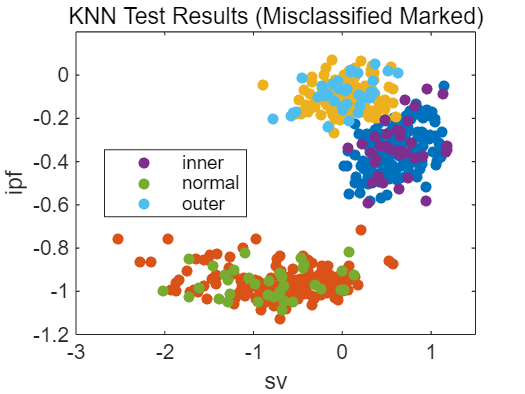

%% Plot Misclassified Test Samples
bad_knn = predTest_knn ~= Ytest_knn;

color = lines(6);
figure;
gscatter(Xtrain_knn(:,1), Xtrain_knn(:,2), Ytrain_knn, color(1:3,:));
hold on;
gscatter(Xtest_knn(:,1), Xtest_knn(:,2), Ytest_knn, color(4:6,:));
plot(Xtest_knn(bad_knn,1), Xtest_knn(bad_knn,2), 'kx', 'MarkerSize',10, 'LineWidth',2);
title("KNN Test Results (Misclassified Marked)");
xlabel(feature1)
ylabel(feature2)
hold off;

## **Section 2-1: Classification on Selected features(Forward)**

Wrapper Type Feature Selection: Sequential Feature Selection

**Use  :  **`inmodel = sequentialfs(fun,X,y)`

fun = @(Xtrain, Ytrain, Xtest, Ytest) ...
       loss(fitcecoc(Xtrain, Ytrain), Xtest, Ytest);

inmodel = sequentialfs(fun, Xtrain, Ytrain);

Xtrain_selected = Xtrain(:, inmodel);
Xtest_selected  = Xtest(:, inmodel);

% Train SVM classifier using the selected feature subset
mdl_svm_selected = fitcecoc(Xtrain_selected, Ytrain);

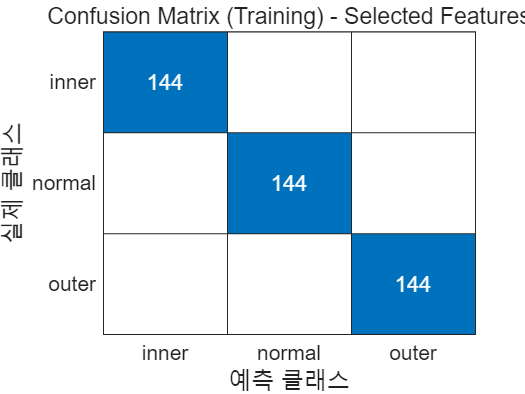

% SFS Train Confusion Matrix(SVM)
predTrain_selected = predict(mdl_svm_selected, Xtrain_selected);
predTrain_selected = categorical(predTrain_selected);

figure;
confusionchart(Ytrain, predTrain_selected);
title("Confusion Matrix (Training) - Selected Features");

trainAccuracy_selected = mean(predTrain_selected == Ytrain);
fprintf("Training Accuracy (Selected Features) = %.4f (%.2f%%)\n", ...
        trainAccuracy_selected, trainAccuracy_selected*100);

Training Accuracy (Selected Features) = 1.0000 (100.00%)


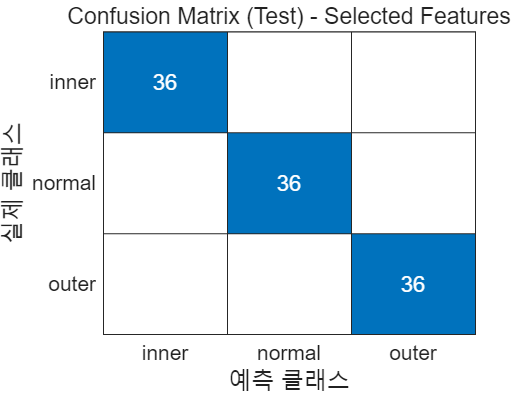

% SFS Test Confusion Matrix(SVM)
predTest_selected = predict(mdl_svm_selected, Xtest_selected);
predTest_selected = categorical(predTest_selected);

figure;
confusionchart(Ytest, predTest_selected);
title("Confusion Matrix (Test) - Selected Features");


testAccuracy_selected = mean(predTest_selected == Ytest);
fprintf("Test Accuracy (Selected Features) = %.4f (%.2f%%)\n", ...
        testAccuracy_selected, testAccuracy_selected*100);

Test Accuracy (Selected Features) = 1.0000 (100.00%)


rng(0)
cvmdl_selected = crossval(mdl_svm_selected, "KFold", 10); %KFold=10

cvLoss_selected = kfoldLoss(cvmdl_selected);
cvAccuracy_selected = 1 - cvLoss_selected;

fprintf("10-Fold CV Loss (Selected Features) = %.4f\n", cvLoss_selected);

10-Fold CV Loss (Selected Features) = 0.0000


fprintf("10-Fold CV Accuracy (Selected Features) = %.4f (%.2f%%)\n", ...
        cvAccuracy_selected, cvAccuracy_selected*100);

10-Fold CV Accuracy (Selected Features) = 1.0000 (100.00%)


%% ===== SFS for KNN =====

fun_knn = @(Xtrain, Ytrain, Xtest, Ytest) ...
    loss(fitcknn(Xtrain, Ytrain, 'NumNeighbors', 3, 'Standardize', true), ...
         Xtest, Ytest);

inmodel_knn = sequentialfs(fun_knn, Xtrain, Ytrain);

Xtrain_knn_selected = Xtrain(:, inmodel_knn);
Xtest_knn_selected  = Xtest(:, inmodel_knn);

%% Train KNN using selected features
mdl_knn_selected = fitcknn(Xtrain_knn_selected, Ytrain, ...
    'NumNeighbors', 3, 'Standardize', true);

%% Training prediction
predTrain_knn_selected = predict(mdl_knn_selected, Xtrain_knn_selected);
predTrain_knn_selected = categorical(predTrain_knn_selected);

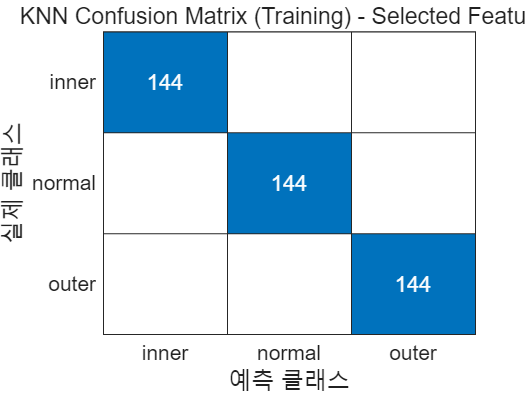

% SFS Train Confusion Matrix(KNN)
figure;
confusionchart(Ytrain, predTrain_knn_selected);
title("KNN Confusion Matrix (Training) - Selected Features");


trainAcc_knn_selected = mean(predTrain_knn_selected == Ytrain);
fprintf("Training Accuracy (KNN + Selected Features) = %.4f (%.2f%%)\n", ...
        trainAcc_knn_selected, trainAcc_knn_selected*100);

Training Accuracy (KNN + Selected Features) = 1.0000 (100.00%)


%% Test prediction
predTest_knn_selected = predict(mdl_knn_selected, Xtest_knn_selected);
predTest_knn_selected = categorical(predTest_knn_selected);

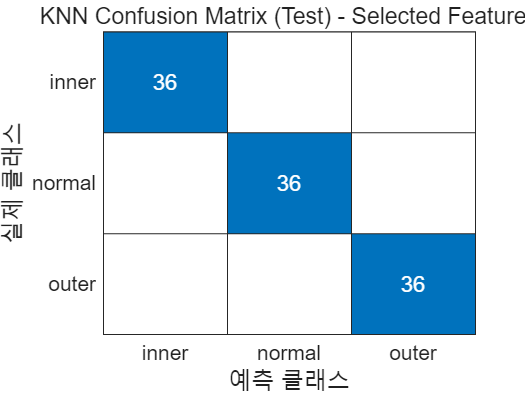

% SFS Test Confusion Matrix(KNN)
figure;
confusionchart(Ytest, predTest_knn_selected);
title("KNN Confusion Matrix (Test) - Selected Features");


testAcc_knn_selected = mean(predTest_knn_selected == Ytest);
fprintf("Test Accuracy (KNN + Selected Features) = %.4f (%.2f%%)\n", ...
        testAcc_knn_selected, testAcc_knn_selected*100);

Test Accuracy (KNN + Selected Features) = 1.0000 (100.00%)


%% Cross Validation
rng(0);
cvmdl_knn_selected = crossval(mdl_knn_selected, 'KFold', 10);
cvLoss_knn_selected = kfoldLoss(cvmdl_knn_selected);

cvAcc_knn_selected = 1 - cvLoss_knn_selected;

fprintf("10-Fold CV Accuracy (KNN + Selected Features) = %.4f (%.2f%%)\n", ...
        cvAcc_knn_selected, cvAcc_knn_selected*100);

10-Fold CV Accuracy (KNN + Selected Features) = 1.0000 (100.00%)


## **Section 2-2: Classification on Selected features(Backward)**

% Backward for SVM

fun_svm = @(Xtrain, Ytrain, Xtest, Ytest) ...
    loss(fitcecoc(Xtrain, Ytrain), Xtest, Ytest);

% Backward elimination
opts = statset('display','iter');   % Plot Progrses
inmodel_svm_bwd = sequentialfs(fun_svm, Xtrain, Ytrain, ...
                               'Direction','backward', ...
                               'Options', opts);

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0
2단계, 1번 열 제거, 기준값 0
3단계, 2번 열 제거, 기준값 0
4단계, 3번 열 제거, 기준값 0
5단계, 4번 열 제거, 기준값 0
6단계, 5번 열 제거, 기준값 0
7단계, 6번 열 제거, 기준값 0
8단계, 7번 열 제거, 기준값 0
9단계, 8번 열 제거, 기준값 0
10단계, 9번 열 제거, 기준값 0
11단계, 10번 열 제거, 기준값 0
12단계, 11번 열 제거, 기준값 0
13단계, 12번 열 제거, 기준값 0
14단계, 13번 열 제거, 기준값 0
15단계, 14번 열 제거, 기준값 0
16단계, 15번 열 제거, 기준값 0
17단계, 16번 열 제거, 기준값 0
18단계, 17번 열 제거, 기준값 0
19단계, 18번 열 제거, 기준값 0
20단계, 19번 열 제거, 기준값 0
21단계, 20번 열 제거, 기준값 0
22단계, 21번 열 제거, 기준값 0
23단계, 22번 열 제거, 기준값 0
24단계, 23번 열 제거, 기준값 0
25단계, 24번 열 제거, 기준값 0
26단계, 25번 열 제거, 기준값 0
27단계, 26번 열 제거, 기준값 0
28단계, 27번 열 제거, 기준값 0
29단계, 28번 열 제거, 기준값 0
30단계, 30번 열 제거, 기준값 0
31단계, 31번 열 제거, 기준값 0
32단계, 32번 열 제거, 기준값 0
33단계, 33번 열 제거, 기준값 0
34단계, 29번 열 제거, 기준값 0
35단계, 34번 열 제거, 기준값 0
36단계, 35번 열 제거, 기준값 0
37단계, 36번 열 제거, 기준값 0
38단계, 37번 열 제거, 기준값 0
39단계, 38번 열 제거, 기준값 0
40단계, 41번 열 제거, 기준값 0
최종적으로 포함된 열: 39 40 42 


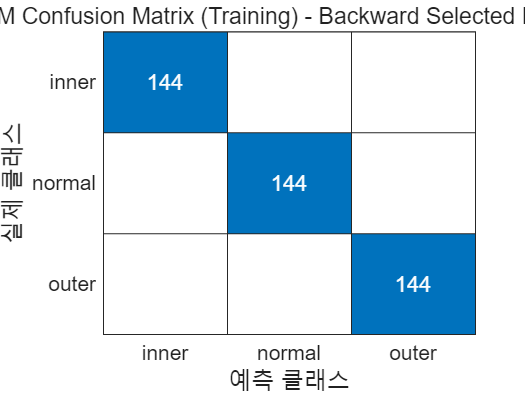

% Selected Feature(SVM)
Xtrain_svm_bwd = Xtrain(:, inmodel_svm_bwd);
Xtest_svm_bwd  = Xtest(:, inmodel_svm_bwd);

% Train SVM
mdl_svm_bwd = fitcecoc(Xtrain_svm_bwd, Ytrain);

%% Training Accuracy
predTrain_svm_bwd = predict(mdl_svm_bwd, Xtrain_svm_bwd);
predTrain_svm_bwd = categorical(predTrain_svm_bwd);

% SBS Train Confusion Matrix(SVM)
figure;
confusionchart(Ytrain, predTrain_svm_bwd);
title("SVM Confusion Matrix (Training) - Backward Selected Features");


trainAcc_svm_bwd = mean(predTrain_svm_bwd == Ytrain);
fprintf("Training Accuracy (SVM + Backward Selected) = %.4f (%.2f%%)\n", ...
        trainAcc_svm_bwd, trainAcc_svm_bwd*100);

Training Accuracy (SVM + Backward Selected) = 1.0000 (100.00%)


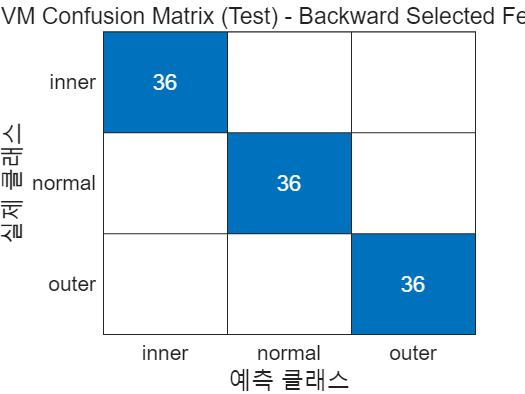

%% Test Accuracy
predTest_svm_bwd = predict(mdl_svm_bwd, Xtest_svm_bwd);
predTest_svm_bwd = categorical(predTest_svm_bwd);

% SBS Test Confusion Matrix(SVM)
figure;
confusionchart(Ytest, predTest_svm_bwd);
title("SVM Confusion Matrix (Test) - Backward Selected Features");


testAcc_svm_bwd = mean(predTest_svm_bwd == Ytest);
fprintf("Test Accuracy (SVM + Backward Selected) = %.4f (%.2f%%)\n", ...
        testAcc_svm_bwd, testAcc_svm_bwd*100);

Test Accuracy (SVM + Backward Selected) = 1.0000 (100.00%)


%% K-fold CV
rng(0)
cvmdl_svm_bwd = crossval(mdl_svm_bwd, 'KFold', 10);
cvLoss_svm_bwd = kfoldLoss(cvmdl_svm_bwd);
cvAcc_svm_bwd = 1 - cvLoss_svm_bwd;

fprintf("10-Fold CV Accuracy (SVM + Backward Selected) = %.4f (%.2f%%)\n", ...
        cvAcc_svm_bwd, cvAcc_svm_bwd*100);

10-Fold CV Accuracy (SVM + Backward Selected) = 1.0000 (100.00%)


% Backward for KNN

fun_knn = @(Xtrain, Ytrain, Xtest, Ytest) ...
    loss(fitcknn(Xtrain, Ytrain, 'NumNeighbors', 3, 'Standardize', true), ...
         Xtest, Ytest);

opts = statset('display','iter');  % Plot Progress
inmodel_knn_bwd = sequentialfs(fun_knn, Xtrain, Ytrain, ...
                               'Direction','backward', ...
                               'Options', opts);

역방향 순차적 특징 선택 시작:
포함된 초기 열: all
포함해야 할 열: none
1단계, 초기 열 사용, 기준값 0
2단계, 1번 열 제거, 기준값 0
3단계, 2번 열 제거, 기준값 0
4단계, 3번 열 제거, 기준값 0
5단계, 4번 열 제거, 기준값 0
6단계, 5번 열 제거, 기준값 0
7단계, 6번 열 제거, 기준값 0
8단계, 7번 열 제거, 기준값 0
9단계, 8번 열 제거, 기준값 0
10단계, 9번 열 제거, 기준값 0
11단계, 10번 열 제거, 기준값 0
12단계, 11번 열 제거, 기준값 0
13단계, 12번 열 제거, 기준값 0
14단계, 13번 열 제거, 기준값 0
15단계, 14번 열 제거, 기준값 0
16단계, 15번 열 제거, 기준값 0
17단계, 16번 열 제거, 기준값 0
18단계, 17번 열 제거, 기준값 0
19단계, 18번 열 제거, 기준값 0
20단계, 19번 열 제거, 기준값 0
21단계, 20번 열 제거, 기준값 0
22단계, 21번 열 제거, 기준값 0
23단계, 22번 열 제거, 기준값 0
24단계, 23번 열 제거, 기준값 0
25단계, 24번 열 제거, 기준값 0
26단계, 25번 열 제거, 기준값 0
27단계, 27번 열 제거, 기준값 0
28단계, 28번 열 제거, 기준값 0
29단계, 30번 열 제거, 기준값 0
30단계, 31번 열 제거, 기준값 0
31단계, 32번 열 제거, 기준값 0
32단계, 33번 열 제거, 기준값 0
33단계, 34번 열 제거, 기준값 0
34단계, 36번 열 제거, 기준값 0
35단계, 38번 열 제거, 기준값 0
36단계, 37번 열 제거, 기준값 0
37단계, 40번 열 제거, 기준값 0
38단계, 41번 열 제거, 기준값 0
39단계, 26번 열 제거, 기준값 0
40단계, 35번 열 제거, 기준값 0
41단계, 39번 열 제거, 기준값 0
최종적으로 포함된 열: 29 42 


Xtrain_knn_bwd = Xtrain(:, inmodel_knn_bwd);
Xtest_knn_bwd  = Xtest(:, inmodel_knn_bwd);

% Train KNN
mdl_knn_bwd = fitcknn(Xtrain_knn_bwd, Ytrain, ...
    'NumNeighbors', 3, 'Standardize', true);

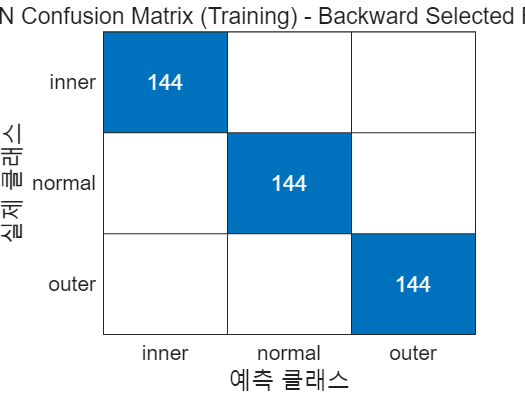

%% Training
predTrain_knn_bwd = predict(mdl_knn_bwd, Xtrain_knn_bwd);
predTrain_knn_bwd = categorical(predTrain_knn_bwd);

% SBS Train Confusion Matrix(SVM)
figure;
confusionchart(Ytrain, predTrain_knn_bwd);
title("KNN Confusion Matrix (Training) - Backward Selected Features");


trainAcc_knn_bwd = mean(predTrain_knn_bwd == Ytrain);
fprintf("Training Accuracy (KNN + Backward Selected) = %.4f (%.2f%%)\n", ...
        trainAcc_knn_bwd, trainAcc_knn_bwd*100);

Training Accuracy (KNN + Backward Selected) = 1.0000 (100.00%)


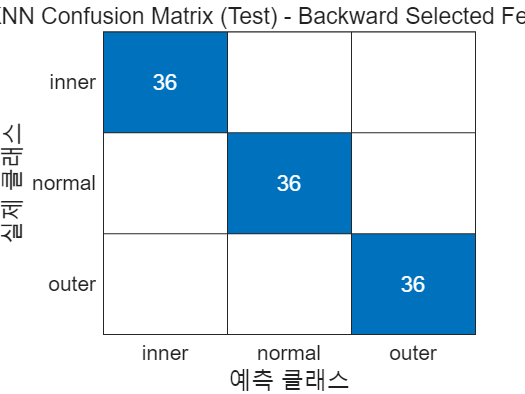

%% Test
predTest_knn_bwd = predict(mdl_knn_bwd, Xtest_knn_bwd);
predTest_knn_bwd = categorical(predTest_knn_bwd);

% SBS Train Confusion Matrix(KNN)
figure;
confusionchart(Ytest, predTest_knn_bwd);
title("KNN Confusion Matrix (Test) - Backward Selected Features");


testAcc_knn_bwd = mean(predTest_knn_bwd == Ytest);
fprintf("Test Accuracy (KNN + Backward Selected) = %.4f (%.2f%%)\n", ...
        testAcc_knn_bwd, testAcc_knn_bwd*100);

Test Accuracy (KNN + Backward Selected) = 1.0000 (100.00%)


%% CV
rng(0)
cvmdl_knn_bwd = crossval(mdl_knn_bwd, 'KFold', 10);
cvLoss_knn_bwd = kfoldLoss(cvmdl_knn_bwd);
cvAcc_knn_bwd = 1 - cvLoss_knn_bwd;

fprintf("10-Fold CV Accuracy (KNN + Backward Selected) = %.4f (%.2f%%)\n", ...
        cvAcc_knn_bwd, cvAcc_knn_bwd*100);

10-Fold CV Accuracy (KNN + Backward Selected) = 1.0000 (100.00%)


## **Section 3: Classification on Reduced Features**

**Use: **[`coeff = pca(X)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644629)`, `[`coeff = pca(X,Name,Value)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644661)

% PCA for SVM
[coeff, scores_train, latent, tsquared, explained, pcaCenter] = pca(Xtrain);

explain_standard = 0.95;

numPC = find(cumsum(explained)/sum(explained) >= explain_standard, 1);

fprintf("Number of PCs for >=95%% variance: %d\n", numPC);

Number of PCs for >=95% variance: 5


coeff_reduced  = coeff(:, 1:numPC);
scores_train_r = scores_train(:, 1:numPC);
[n, p] = size(Xtrain);
meanX = mean(Xtrain, 1);

Xfit = repmat(meanX, n, 1) + scores_train_r * coeff_reduced';

%% Train SVM with PCA-reduced train data
mdl_pca = fitcecoc(scores_train_r, Ytrain);

%% K-fold CV for PCA SVM
cvmdl_pca = crossval(mdl_pca);           
cvAccuracy_pca = 1 - kfoldLoss(cvmdl_pca);

fprintf("PCA Reduced Feature 10-fold CV Accuracy = %.4f (%.2f%%)\n", ...
        cvAccuracy_pca, cvAccuracy_pca*100);

PCA Reduced Feature 10-fold CV Accuracy = 1.0000 (100.00%)


%% Convert Test data to PCA-reduced dimension
ntest = size(Xtest,1);
mu = repmat(pcaCenter, ntest, 1);

Xtest_pca = (Xtest - mu) * coeff_reduced;

pred_pca = predict(mdl_pca, Xtest_pca);
pred_pca = categorical(pred_pca);

testAcc_pca = mean(pred_pca == Ytest);

fprintf("PCA Test Accuracy = %.4f (%.2f%%)\n", testAcc_pca, testAcc_pca*100);

PCA Test Accuracy = 1.0000 (100.00%)


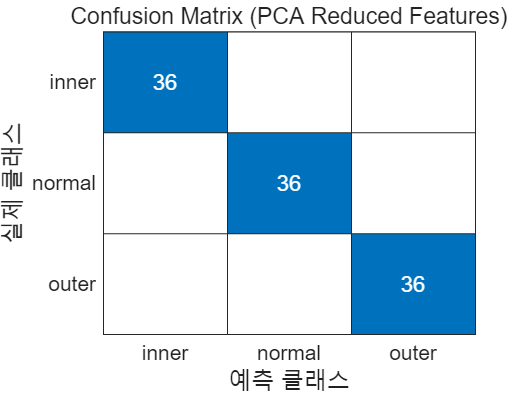

% PCA Test Confusion Matrix(SVM)
figure;
confusionchart(Ytest, pred_pca);
title("Confusion Matrix (PCA Reduced Features)");

%% ===== PCA for Dimensionality Reduction =====
[coeff, scores_train, latent, tsquared, explained, pcaCenter] = pca(Xtrain);


% Select number of principal components to retain 95% variance
var_threshold = 0.95;
numPC = find(cumsum(explained)/sum(explained) >= var_threshold, 1);

fprintf("Number of PCs for >=95%% variance: %d\n", numPC);

Number of PCs for >=95% variance: 5


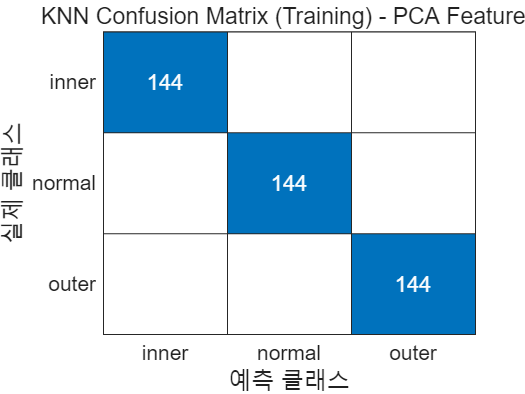


% Reduced PCA training data
Xtrain_pca = scores_train(:, 1:numPC);

% Reduced PCA test data
ntest = size(Xtest, 1);
mu = repmat(pcaCenter, ntest, 1);
Xtest_pca = (Xtest - mu) * coeff(:, 1:numPC);

%% ===== Train KNN on PCA-reduced features =====
K = 3;
mdl_knn_pca = fitcknn(Xtrain_pca, Ytrain, ...
    'NumNeighbors', K, 'Standardize', true);

%% ===== Training Prediction =====
predTrain_knn_pca = predict(mdl_knn_pca, Xtrain_pca);
predTrain_knn_pca = categorical(predTrain_knn_pca);

figure;
confusionchart(Ytrain, predTrain_knn_pca);
title("KNN Confusion Matrix (Training) - PCA Features");


trainAcc_knn_pca = mean(predTrain_knn_pca == Ytrain);
fprintf("Training Accuracy (KNN + PCA) = %.4f (%.2f%%)\n", ...
        trainAcc_knn_pca, trainAcc_knn_pca*100);

Training Accuracy (KNN + PCA) = 1.0000 (100.00%)


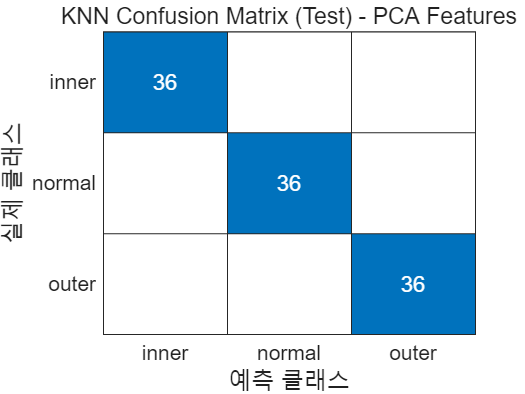


%% ===== Test Prediction =====
predTest_knn_pca = predict(mdl_knn_pca, Xtest_pca);
predTest_knn_pca = categorical(predTest_knn_pca);

figure;
confusionchart(Ytest, predTest_knn_pca);
title("KNN Confusion Matrix (Test) - PCA Features");


testAcc_knn_pca = mean(predTest_knn_pca == Ytest);
fprintf("Test Accuracy (KNN + PCA) = %.4f (%.2f%%)\n", ...
        testAcc_knn_pca, testAcc_knn_pca*100);

Test Accuracy (KNN + PCA) = 1.0000 (100.00%)



%% ===== K-Fold Cross Validation =====
rng(0)
cvmdl_knn_pca = crossval(mdl_knn_pca, 'KFold', 10);
cvLoss_knn_pca = kfoldLoss(cvmdl_knn_pca);
cvAcc_knn_pca = 1 - cvLoss_knn_pca;

fprintf("10-Fold CV Accuracy (KNN + PCA) = %.4f (%.2f%%)\n", ...
        cvAcc_knn_pca, cvAcc_knn_pca*100);

10-Fold CV Accuracy (KNN + PCA) = 1.0000 (100.00%)


## Discussion 

First, machine learning was performed using SVM, which utilized all features. SVM is an algorithm that finds the boundary line that best distinguishes between classes. In other words, it finds the boundary line that maximizes the distance (margin) from the vector, i.e., the boundary line that is furthest from the class. After running the model separately in Train (8) and Test (2), the Train model accurately predicted all training data without a single error. This resulted in a trainLoss of 0. The Test model now determines whether this represents overfitting. The Test model showed that while the normal and outer models correctly predicted all 36 datasets, the inner model predicted only 31 of the 36, with five false positives. However, the final accuracy exceeded 95%, so it was determined that overfitting did not occur. Furthermore, the performance was averaged using K-Fold (10), resulting in a CV Loss of 0.0486 and an accuracy of 95.14%. This time, we performed machine learning using KNN. KNN is a model that determines the class of new data by observing the surrounding data. Similarly, we divided the data into Train (8) and Test (2) and ran the test. In KNN, the Train model tended to perform worse than the SVM. It misclassified 5 out of 432 data, resulting in a TrainLoss of 0.0116. In contrast, the Test model correctly classified all 144 data, achieving 100% accuracy. Overall, KNN outperformed SVM. This is likely due to the CWRU data being divided into inner, normal, and outer states, each of which is relatively clear. This time, we used feature selection techniques to perform both SVM and KNN. Feature selection is divided into forward and backward phases. Forward phase starts with a specified number of features, with no features used, and then adds features one by one. If performance improves with the addition of a feature, the next feature is added. If performance does not improve, the process stops. Conversely, backward phase starts with all features used and then removes features one by one. This method involves removing features and, if performance improves, removing the next feature; otherwise, stopping. When applying forward and backward feature selection techniques to SVM and KNN, both achieved 100% accuracy for both the train and test models. If all features are present in a dataset, only a small portion is actually important. However, using all features also results in the use of unimportant features, which reduces accuracy. On the other hand, using feature selection techniques appears to improve accuracy by either including only important features (forward) or removing unimportant features (backward). Finally, PCA is a technique for reducing the number of features. To achieve this, PCA creates axes in order of greatest data variance. If the number of features is significantly larger than the current number, SFS can take a long time to compute, and if preprocessing is not done properly, the probability of selecting incorrect features increases. In such cases, PCA is preferable to feature selection. The code assumes a variance of 95% or higher, resulting in a required dimensionality of 5. Similarly, when running both SVM and KNN in PCA, the accuracy of both the Train Model and Test Model reached 100%.